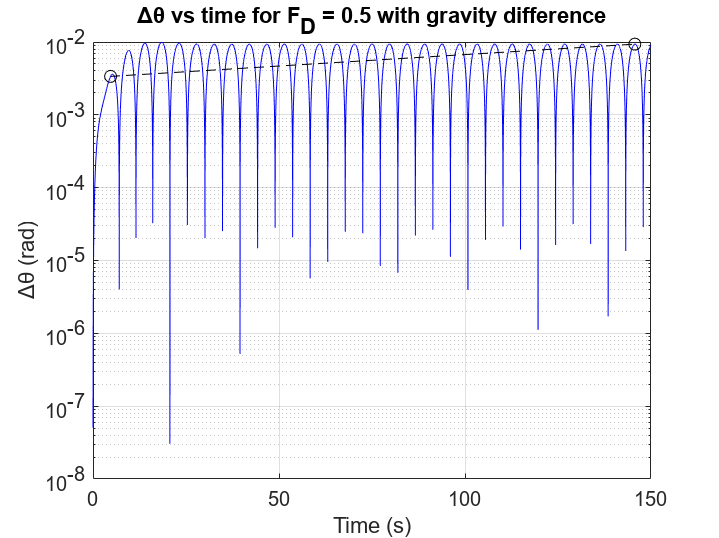

% Define the constants for the pendulum
g = 9.8;  % Acceleration due to gravity (m/s^2)
delta_g = 0.05;  % Small difference in the acceleration due to gravity
l = 9.8;  % Length of the pendulum (m)
q = 0.5;  % Damping coefficient
Omega_D = 2/3;  % Driving frequency
theta0 = 0.2;  % Initial angle (rad)
omega0 = 0;  % Initial angular velocity (rad/s)
t_max = 150;  % Max time for simulation
dt = 0.04;  % Time step size

% Define the pendulum equation with gravity as a parameter
pendulum_eq = @(t, y, Fd, g) [y(2); -(g/l)*sin(y(1)) - q*y(2) + Fd*sin(Omega_D*t)];

% Define options for ode solver to use a fixed time step
options = odeset('MaxStep', dt, 'InitialStep', dt, 'RelTol', 1e-5);

% Simulate for Fd = 0.5 with original gravity
[t1, y1] = ode45(@(t, y) pendulum_eq(t, y, 0.5, g), [0, t_max], [theta0, omega0], options);

% Simulate for Fd = 0.5 with modified gravity
[t1_prime, y1_prime] = ode45(@(t, y) pendulum_eq(t, y, 0.5, g + delta_g), [0, t_max], [theta0, omega0], options);

% Calculate Δθ for Fd = 0.5 with gravity difference
delta_theta1 = abs(wrapToPi(y1(:, 1)) - wrapToPi(y1_prime(:, 1)));

% Simulate for Fd = 1.2 with original gravity
[t2, y2] = ode45(@(t, y) pendulum_eq(t, y, 1.2, g), [0, t_max], [theta0, omega0], options);

% Simulate for Fd = 1.2 with modified gravity
[t2_prime, y2_prime] = ode45(@(t, y) pendulum_eq(t, y, 1.2, g + delta_g), [0, t_max], [theta0, omega0], options);

% Calculate Δθ for Fd = 1.2 with gravity difference
delta_theta2 = abs(wrapToPi(y2(:, 1)) - wrapToPi(y2_prime(:, 1)));

% Plotting Δθ vs time for Fd = 0.5
figure;
semilogy(t1, delta_theta1, 'b-');
title('Δθ vs time for F_D = 0.5 with gravity difference');
xlabel('Time (s)');
ylabel('Δθ (rad)');
grid on;
hold on;

y = [0.00337175 0.00935];
x = [4.72 145.65];
plot(x,y,'ko--');
hold off;

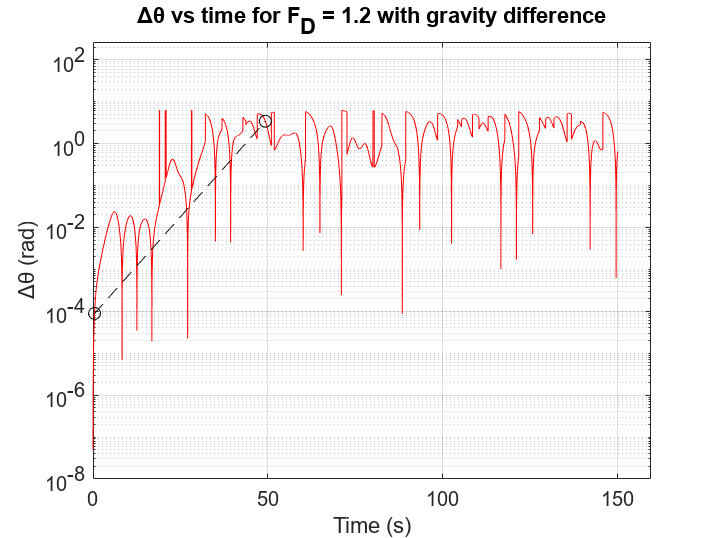


% Plotting Δθ vs time for Fd = 1.2
figure;
semilogy(t2, delta_theta2, 'r-');
title('Δθ vs time for F_D = 1.2 with gravity difference');
xlabel('Time (s)');
ylabel('Δθ (rad)');
grid on;
hold on;

y = [8.8981e-05 3.4114];
x = [0.44 49.28];
plot(x,y,'ko--');
hold off;



% Display the figures
drawnow;
